# Exercise 3

Use optimization techniques to perform pattern synthesis. 

Many popular beamforming techniques can be expressed as optimization problems. For example, the popular minimum variance distortionless response (MVDR) beamformer is used to minimize the total noise output while preserving the signal from a given direction. Mathematically, the MVDR beamforming weights is an optimization problem.

## Load Uniform Linear Array

% load the URA we created in the previous exercise
load ex2_array.mat
p_rec = ura8_8;

% Get the positions of the antenna elements
pos_rec = getElementPosition(p_rec); 

% Since this is a planar array, the position of elements in x are all 0 and
% can be ignored
pos_yz_rec = pos_rec(2:3,:);

% Define the desired main beam angle and interference / null angles      
ang_i = [-70 -40 -20];              
ang_d = 15;         

## Calculate the covariance matrix of the arraysteering vector 

% Calculate the covariance matrix which will be used later
noisePower = db2pow(-10); 
Rn = sensorcov(pos_yz_rec,ang_i,noisePower);


## Define the Side Lobe Levels

% Define the SLL (as pair of angles and dB vectors at that angle)

%Left side
ANGml = -90:.2:-22.5;                       % mask angles for left SLLs
SLLml = linspace(-75,-45,numel(ANGml));     % left SLLs that decreases linearly from −45db to −75dB

%Right side
ANGmr = 27.5:0.2:90;                        % mask angles for right SLLs
SLLmr = linspace(-45,-75,numel(ANGmr));     % right SLLs that decrease linearly from −45dB to −75dB

%Combine both sides
ANGm = [ANGml ANGmr; ANGml ANGmr];          % concatinate mask angles along 2D
SLLm = [SLLml SLLmr];                       % concatinate mask SLL

## Use the minimum-variance array pattern synthesis algorithm

%-------------------------------
% ADD CODE HERE
% Hint: use the minvarweights function to calculate array weights
% Type >> 'doc minvarweights' into the command line interface for more information. 

% Use the calculated element positions, desidered angle, covariance matrix as
% input variables and enter as Name-Value pairs, the 'Null Angle',
% 'MaskAngle' and 'MaskSidelobeLevel'
%---------------------------------

OptimizedWeightsSLLs = minvarweights(pos_yz_rec, ang_d, Rn, NullAngle= ang_i, ...
    MaskAngle=ANGm, MaskSidelobeLevel = SLLm);


## Plot and view the resultant pattern with mask overlay

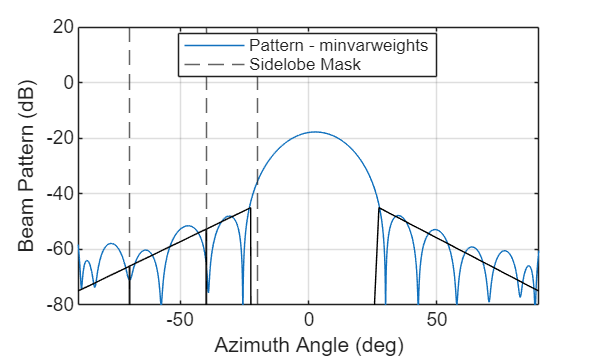

ang_plot = [-90:0.1:90;-90:0.1:90];

% % Calculate array pattern
sv_plot = steervec(pos_yz_rec,ang_plot);
Pattern2 = OptimizedWeightsSLLs'*sv_plot;

% Plot the pattern
plot(-90:.1:90,mag2db(abs(Pattern2)))
xline(ang_i,"--")
xlabel("Azimuth Angle (deg)")
ylabel("Beam Pattern (dB)")
axis([-90 90 -80 20])
grid on

% Plot the mask with nulls and SLLs
hold on
[AngMask,IA] = sort([ANGml ANGmr ang_i]);
SLLmask = [SLLm -1000*ones(1,size(ang_i,2))];
plot(AngMask,SLLmask(IA),'k')
legend(["Pattern - minvarweights" "Sidelobe Mask"], ...
    Location="best")
hold off

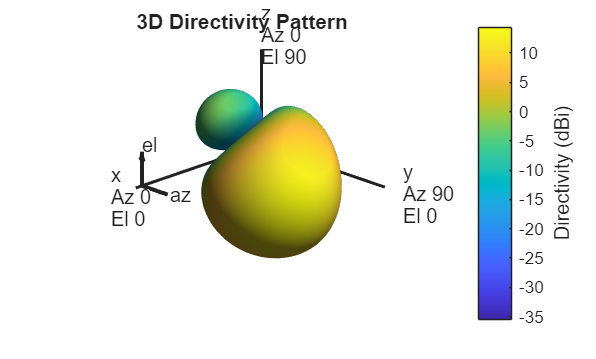


% View the 3D directivity pattern using the pattern function
pattern(p_rec,3e8,Weights=OptimizedWeightsSLLs);